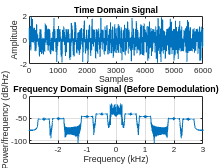

%% lab 2_ex2
clear;
close all;
load noisySignal.mat;

% Plot the signal before demodulation
figure;
subplot(2,1,1);
plot(signal);
title('Time Domain Signal');
xlabel('Samples');
ylabel('Amplitude');

subplot(2,1,2);
periodogram(signal, [], [], R_s, 'centered');
title('Frequency Domain Signal (Before Demodulation)');

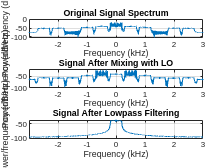


%% Section 2
% Demodulation PAM
% Define Sampling Vector
n = (1:1:length(signal))./R_s; % Sample vector for the local oscillator

% Define Center Frequency
fc = 500;

% Create Local Oscillator
LO = cos(2*pi*n*fc); % Local oscillator for mixing

% Design a Lowpass Filter
% CORRECTED: Passband frequency must be less than stopband frequency
filt_signal = designfilt('lowpassfir', ...
    'PassbandFrequency', 0.25e3, ...    % Changed from 0.5e3
    'StopbandFrequency', 0.5e3, ...    z % Changed from 0.25e3
    'PassbandRipple', 2, ...
    'StopbandAttenuation', 60, ...
    'SampleRate', 10e3, ...
    'DesignMethod', 'kaiserwin');

% Demodulate: Mix with Local Oscillator and Filter
s_c = signal.*LO; % Output after local oscillator - converted to baseband
s_f = filter(filt_signal, s_c); % Output after LPF

% Plot PSDs
figure;
subplot(3,1,1);
periodogram(signal, [], [], R_s, 'centered');
title('Original Signal Spectrum');

subplot(3,1,2);
periodogram(s_c, [], [], R_s, 'centered');
title('Signal After Mixing with LO');

subplot(3,1,3);
periodogram(s_f, [], [], R_s, 'centered');
title('Signal After Lowpass Filtering');

## Exercise 3: Demodulating and decoding line coded messages

%% Exercise 3:

load sharedChannel.mat;

% Plot the PSD of the signals in the channel
figure;
periodogram(signal, [], [], R_s, 'centered');

Unrecognized function or variable 'signal'.

title('Spectrum of Shared Channel Signal');

% Sample rate
R_s = 10000; % 10 kHz

% Carrier frequencies
f_1 = 1000;
f_2 = 2500;
f_3 = 4000;

LO_1 = cos(2*pi*f_1*t_1);
LO_2 = cos(2*pi*f_2*t_2);
LO_3 = cos(2*pi*f_3*t_3);

q_1 = shareChannel .* LO_1;
q_2 = shareChannel .* LO_2;
q_3 = shareChannel .* LO_3;

% Design the LPF
% changing passband and stopband of the low pass filter as it 
% becomes lower the message becomes more clear 
LPF = designfilt('lowpassfir', 'StopbandFrequency', 0.5e3, ...
    'PassbandFrequency' , 0.1e3, 'PassbandRipple', 2, ...
    'StopbandAttenuation', 60, 'SampleRate', 10e3, ...
    'DesignMethod', 'kaiserwin');

% Filter the demodulated signals
r_1 = filter(LPF, q_1);
r_2 = filter(LPF, q_2);
r_3 = filter(LPF, q_3);

message_1 = binaryToChar(r_1*2, 1, 'unipolarNRZ')
message_2 = binaryToChar(r_2*2, 2, 'bipolarRZ')
message_3 = binaryToChar(r_3*2, 3, 'polarNRZ')